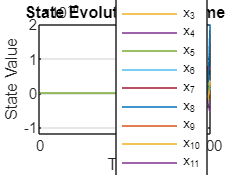

% Clear the workspace and close all figures
clc; clear; close all;
t_span = 0:0.01:100;
% Solve the ODE and obtain the state vector
[t, x] = ode45(@nonlinear_lqg, t_span, [0; 0; 0.5; 0; 0.6; 0;0;0;0;0;0;0]);


figure;
plot(t, x(:, 1),  'DisplayName', 'x_1');
hold on;
plot(t, x(:, 2),  'DisplayName', 'x_2');
plot(t, x(:, 3),  'DisplayName', 'x_3');
plot(t, x(:, 4),  'DisplayName', 'x_4');
plot(t, x(:, 5),  'DisplayName', 'x_5');
plot(t, x(:, 6),  'DisplayName', 'x_6');
plot(t, x(:, 7),  'DisplayName', 'x_7');
plot(t, x(:, 8),  'DisplayName', 'x_8');
plot(t, x(:, 9),  'DisplayName', 'x_9');
plot(t, x(:, 10), 'DisplayName', 'x_{10}');
plot(t, x(:, 11), 'DisplayName', 'x_{11}');
plot(t, x(:, 12), 'DisplayName', 'x_{12}');

xlabel('Time');
ylabel('State Value');
title('State Evolution Over Time');
legend('Location', 'Best');
grid on;
hold off;

function dx = nonlinear_lqg(t, x)
    dx = zeros(6,1);
    g = 9.8;
    M = 1000;
    m1 = 100;
    m2 = 100;
    l1 = 20;
    l2 = 10;
    
    % System matrices
    A = [0 1 0 0 0 0;
        0 0 ((-g*m1)/M) 0 ((-g*m2)/M) 0;
        0 0 0 1 0 0;
        0 0 ((-g*(M+m1))/(M*l1)) 0 -((g*m2)/(M*l1)) 0;
        0 0 0 0 0 1;
        0 0 ((-g*m1)/(M*l2)) 0 ((-g*(M+m2))/(M*l2)) 0 ];
    
    B = [0;
        (1/M);
        0;
        (1/(M*l1));
        0;
        (1/(M*l2))];
    C = eye(6);
    D = 0;

    
    Q = 10 * eye(6);
    R = 0.001;

    C1 = [1 0 0 0 0 0];

    [K,~,~] = lqr(A, B, Q, R);
    F = -K*x(1:6);

    vd=0.3*eye(6); %process noise
    vn=1; %measurement noise
    
    K1 = lqr(A',C1',vd,vn);
    sd = (A-K1'*C1)*x(7:12);

    dx(1) = x(2);
    dx(2) = (-m1*g*sin(x(3))*cos(x(5)) - m2*g*sin(x(5))*cos(x(5)) - m1*l1*x(4)^2*sin(x(3))-m2*l2*x(6)^2*sin(x(5))+F)/(M+m1+m2-m1*cos(x(3))^2-m2*cos(x(5))^2);
    dx(3) = x(4);
    dx(4) = (-m1*g*sin(x(3))*cos(x(5)) - m2*g*sin(x(5))*cos(x(5)) - m1*l1*x(4)^2*sin(x(3))-m2*l2*x(6)^2*sin(x(5))+F)/(l1*(M+m1+m2-m1*cos(x(3))^2-m2*cos(x(5))^2)) - (g*sin(x(3)))/l1;
    dx(5) = x(6);
    dx(6) = (-m1*g*sin(x(3))*cos(x(5)) - m2*g*sin(x(5))*cos(x(5)) - m1*l1*x(4)^2*sin(x(3))-m2*l2*x(6)^2*sin(x(5))+F)/(l2*(M+m1+m2-m1*cos(x(3))^2-m2*cos(x(5))^2)) - (g*sin(x(5)))/l2;
    dx(7) = x(2) - x(10);
    dx(8) = dx(2) - sd(2);
    dx(9) = x(4) - x(11);
    dx(10) = dx(4) - sd(4);
    dx(11) = x(6) - x(12);
    dx(12) = dx(6) - sd(6);
end